# Lab12: Joint assimilation of navigation data coming from different sources

Team1: Dmitry Shadrin, Eugenii Israelit @Skoltech

clc; clear; close all;
addpath('functions/');

n = 500;

x1 = 1000;
vx1 = 100;
y1 = 1000;
vy1 =100;
t = 2; 

sigmaA = 0.3;
AccX = normrnd(0, sigmaA, 1, n );
AccY = normrnd(0, sigmaA, 1, n );
X = calcTrajectory11( AccX, x1, vx1, t);
Y = calcTrajectory11( AccY, y1, vy1, t);

D = sqrt( X.^2 + Y.^2 );  
B = atan( X ./ Y );





sigmaB = 0.004;
sigmaD = 50;
sigmaBodd = 0.001;

ErrSumextrD=0;
ErrSumfiltrD=0;
ErrSumextrB=0;
ErrSumfiltrB=0;
M=500;

for i=1:M
    DNoise = normrnd(0,sigmaD,1,n);
    BNoise = normrnd(0,sigmaB,1,n);
    BNoiseOdd = normrnd(0,sigmaBodd,1,n);
    
    Z=zeros(2,n);
    for i=1:n
        if mod(i,2)==0
            Z(:,i) = [0; B(i)+BNoise(i)];
        else
            Z(:,i) = [D(i)+DNoise(i); B(i)+BNoiseOdd(i)];
        end
    end
    
    xm1 = Z(1,1)*sin(Z(2,1));
    xm2 = Z(1,3)*sin(Z(2,3));
    ym1 = Z(1,1)*cos(Z(2,1));
    ym2 = Z(1,3)*cos(Z(2,3));
    
    z0 = [ xm2; (xm2-xm1)/2*t; ym2; (ym2-ym1)/2*t ];
    
    ZX = Z(1,:).*sin(Z(2,:));
    ZY = Z(1,:).*cos(Z(2,:));
    
    P = [ 10^10 0 0 0; 0 10^10 0 0; 0 0 10^10 0; 0 0 0 10^10 ];
    F = [ 1 t 0 0; 0 1 0 0; 0 0 1 t; 0 0 0 1 ]; 
    G = [ (t^2)/2 0; t 0; 0 (t^2)/2; 0 t ];
    Q = G * G' * sigmaA^2;
    R1 = [ sigmaD^2 0; 0 sigmaB^2 ];
    R2 =  sigmaBodd^2 ;
    
    
    [Xk,Dmextr,Dmfiltr,Bmextr,Bmfiltr] = calcKalmanExtended12(Z, z0, F, P, Q, R1, R2);
    
    Dk=sqrt(Xk(1,:).^2+Xk(3,:).^2);
    Bk=atan(Xk(1,:)./Xk(3,:)); 
    
    ErrCurextrD = ( Dmextr - D).^2;    
    ErrCurfiltrD = (Dmfiltr - D).^2;
    ErrCurextrB = ( Bmextr - B).^2;
    ErrCurfiltrB = (Bmfiltr - B).^2;
    
    ErrSumextrD = ErrSumextrD +  ErrCurextrD;
    ErrSumfiltrD = ErrSumfiltrD +  ErrCurfiltrD;
    ErrSumextrB = ErrSumextrB +  ErrCurextrB;
    ErrSumfiltrB = ErrSumfiltrB +  ErrCurfiltrB;

end
% Xk_ = calcKalmanExtended12_(Z, z0, F, P, Q, R_)



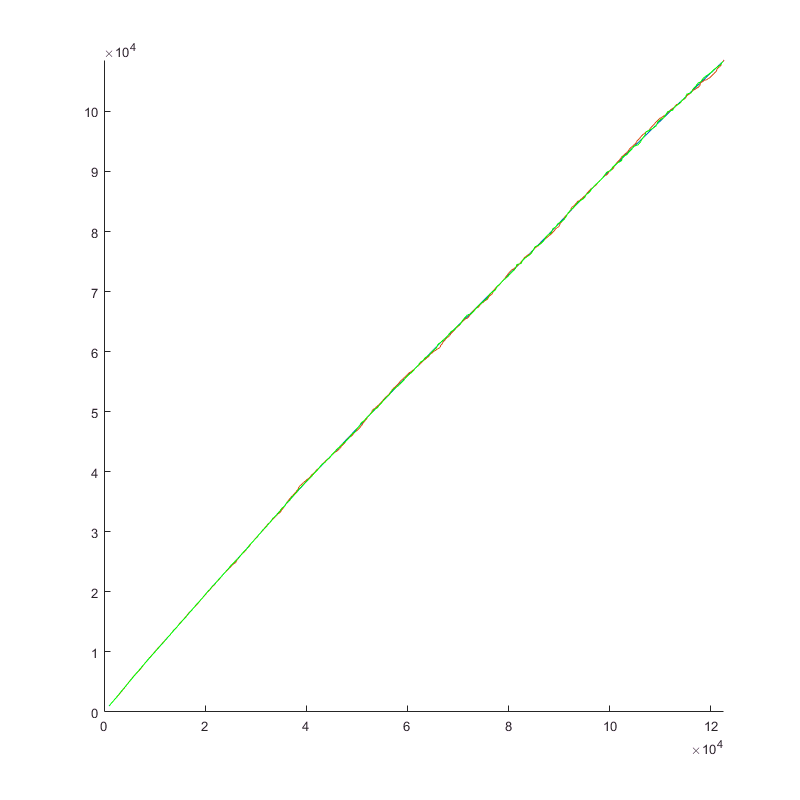

figure ('position', [0, 0, 800, 800]); hold on; 
    plot(X(1:end),Y(1:end)); hold on;
    plot(Xk(1,4:end),Xk(3,4:end));
    plot(ZX(1:2:end), ZY(1:2:n), 'green');
    axis([0 inf 0 inf]);

    
       
FinalErrorextrD = (  ErrSumextrD./M ).^0.5;
FinalErrorfiltrD = (  ErrSumfiltrD./M ).^0.5;
FinalErrorextrB = (  ErrSumextrB./M ).^0.5;
FinalErrorfiltrB = (  ErrSumfiltrB./M ).^0.5;


8. Comparing estimation results with measurement errors of D and B.

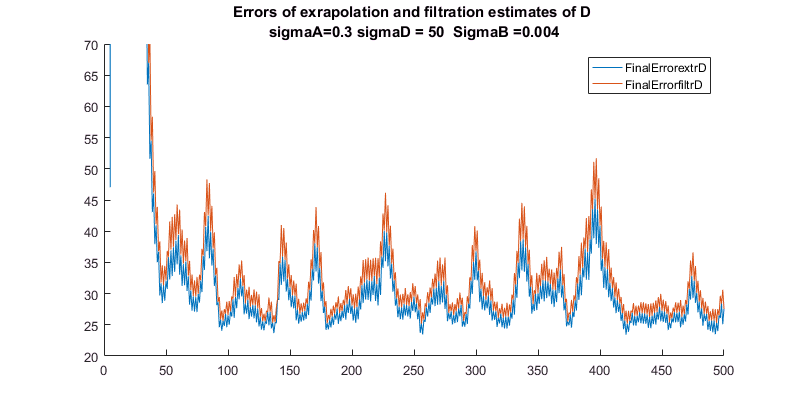


figure('position', [0, 0, 800, 400]); hold on;
    plot(FinalErrorfiltrD);
    plot(FinalErrorextrD);
    title( sprintf ('Errors of exrapolation and filtration estimates of D \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
    legend('FinalErrorextrD', 'FinalErrorfiltrD'); 
    ylim([20 70]);

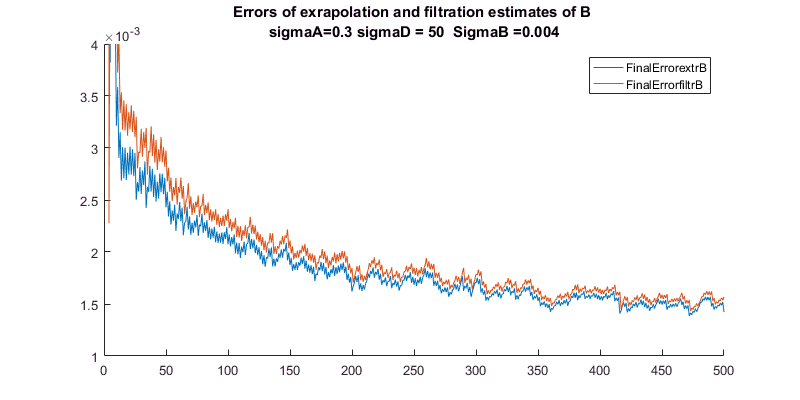


figure('position', [0, 0, 800, 400]); hold on;
    plot(FinalErrorfiltrB);
    plot(FinalErrorextrB);
    title( sprintf ('Errors of exrapolation and filtration estimates of B \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
    legend('FinalErrorextrB', 'FinalErrorfiltrB'); 
    ylim([0.001 0.004]);

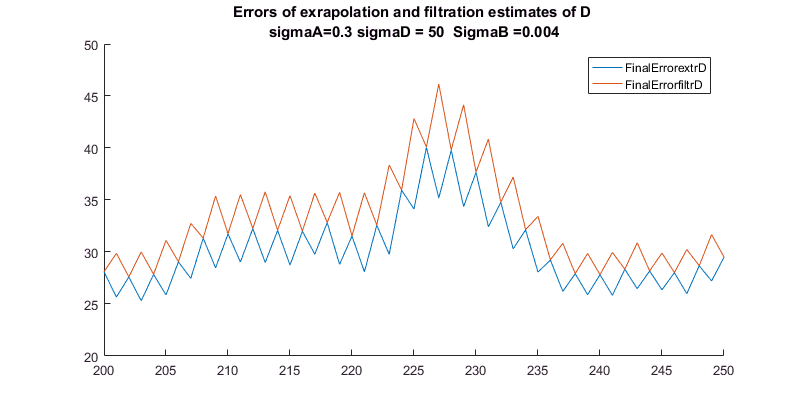

    
figure('position', [0, 0, 800, 400]); hold on;
    plot(FinalErrorfiltrD);
    plot(FinalErrorextrD);
    title( sprintf ('Errors of exrapolation and filtration estimates of D \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
    legend('FinalErrorextrD', 'FinalErrorfiltrD'); 
    axis([200 250 20 50]);

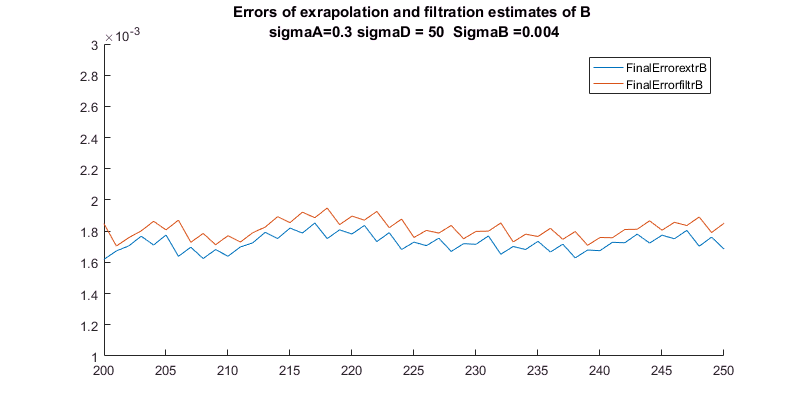

    
figure('position', [0, 0, 800, 400]); hold on;
    plot(FinalErrorfiltrB);
    plot(FinalErrorextrB);
    title( sprintf ('Errors of exrapolation and filtration estimates of B \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
    legend('FinalErrorextrB', 'FinalErrorfiltrB'); 
    axis([200 250 0.001 0.003]);

Conclusion:

Accuracy of estimation of angle B varies from odd to even because on every even step we have a much better precision of angle sensor, but on the next step error encreases back

Accuracy of estimation of distance D varies from odd to even because on every even step we have lack of sensor data 